## **EEGLAB OpenNeuro to DL pipeline**

In this example, we present the pipeline that downloads the [EEG dataset](https://openneuro.org/datasets/ds003061/versions/1.1.2) from [OpenNeuro](https://docs.openneuro.org/user_guide.html) archive [1], pre-processes it using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php) toolbox [2] and formats as input for deep learning-based classification. The data was collected at the Meditation Research Institute (MRI) in Rishikesh, India under the supervision of Arnaud Delorme, PhD ([Swartz Center for Computational Neuroscience](https://sccn.ucsd.edu/)). The data is stored in a [BIDS](https://bids.neuroimaging.io/) format [3], a standard defining the organization of neuroimaging/accompanying behavioral data, as well as the relevant metadata, facilitating the data sharing and reproducibility.

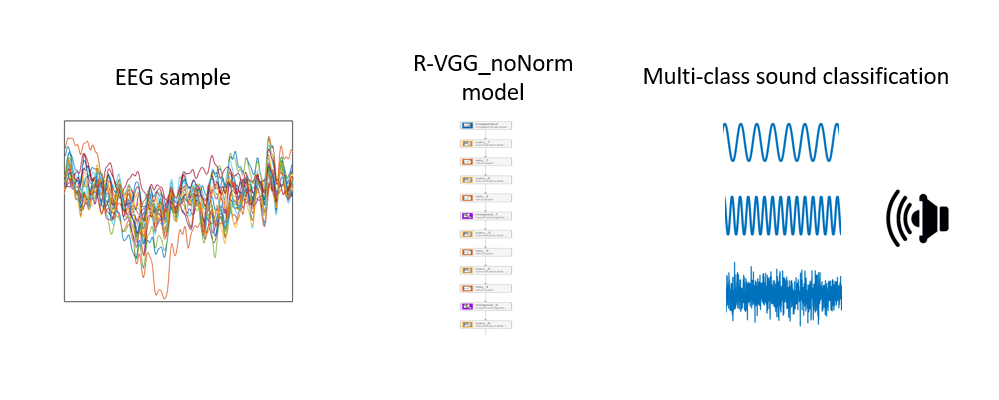

**Background on Dataset**

Recording was performed using the standard [**10-20 EEG system**](https://en.wikipedia.org/wiki/10%E2%80%9320_system_(EEG)) (Active Two Biosemi system, Biosemi Inc.), with 1024 Hz sampling rate. The data in OpenNeuro dataset was subsequently resampled at 256 Hz. Individual samples consist of 1 sec signal across 144 channels, spanning the time window between the two consecutive tone onsets.

**Background on Example**

In this example, we are demonstrating the binary (two classes) classification of visual stimuli based on the scalp EEG recordings. For each stimulus, the time window of 0-0.5 sec relative to stimulus onset is used for model training/inference. 

**BIDS Format**

BIDS format [3] defines the dataset structure and minimum information the dataset needs to contain. The EEG data files could be stored as one of the standard EEG formats (e.g. edf, EEGLAB, NWB). The EEG files in this dataset are stored in *.set format, produced by EEGLAB toolbox. The EEGLAB `pop_importbids` function downloads the BIDS dataset from the online repository and puts it in the EEGLAB format. 

curr_env = getenv; %checking if it's running on MATLAB Online or locally

if isKey(curr_env,"MW_DDUX_APP_NAME")==1 & curr_env("MW_DDUX_APP_NAME")=='MATLAB_ONLINE'
    environment = 'online';
elseif isKey(curr_env,"MW_DDUX_APP_NAME")==0
    environment = 'local';
end

curr_dir = pwd;
if strcmp(environment, 'online')==1
    addpath MATLAB Add-Ons/Collections/EEGLAB;%check if it's already in online repo
    addpath '/MATLAB Drive/Repositories/study_ml';
else
    if exist('eeglab','dir')==1
        eeglab;%
    elseif exist('eeglab','dir')==7
        curr_dir = pwd;
        addpath(sprintf('%s/eeglab',curr_dir));%add on can also work locally. also add study_ml
        %generalize local vs. online
        eeglab;
    else
        curr_dir = pwd;
        gitclone('https://github.com/sccn/eeglab');%shallow clone option 
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    end
end

 
gitclone('https://github.com/sccn/bids-matlab-tools');
addpath(sprintf('%s/bids-matlab-tools',curr_dir));
addpath '/MATLAB Drive/Repositories/study_ml';
 


%fullfile to build path to work on Linux

% Build the path of the selected dataset
base_dir = pwd;
dataset_ID = 'ds002680';

tic
download_shrink_dataset(dataset_ID);%takes about 2min to download 20% of the dataset
toc

filePath = sprintf('%s/%s',base_dir,dataset_ID);
out_dir = sprintf('%s/DL',base_dir);
tic
[STUDY, ALLEEG] = pop_importbids_integrated(filePath, environment, 'eventtype', 'value', 'outputdir', out_dir);
toc%this also takes about 2.5 min 

%use arraydatastore for both
%put this inside the function and use the environment input argument

The pop_importbids function provides two outputs, **STUDY** (the EEGLAB structure defining the group analysis parameters) and **ALLEEG** (the structure containing all the loaded EEG datasets). 

**ALLEEG** is a structure with the first dimension equaling the number of loaded dataset.

- ALLEEG.**filename** - contains the filenames

- ALLEEG.**subject** - subject labels

- ALLEEG.**chanlocs** - channel labels and respective anatomical coordinates

- ALLEEG.**event** - information on trial timestamps and presented stimuli

- ALLEEG.**data** - EEG time series, organized as a matrix (n of channels x n of samples)

**Exploring the Dataset **

We can check the number of datasets and unique subjects.

dataset_info(ALLEEG);

## Preparing the data for DL training/inference format

`pop_studydl` EEGLAB function exports the EEG signals stored in EEGLAB structure into ML/DL data format. 

tic
if strcmp(environment,'local')==1
    [ALLEEG] = pop_studydl_integrated(STUDY, ALLEEG, environment,'outputdir', fullfile(base_dir, 'ML_EXPORT'));
elseif strcmp(environment,'online')==1
    [ALLEEG, samples_all, sample_ID_all, labels_all] = pop_studydl_integrated(STUDY, ALLEEG, environment, 'outputdir', fullfile(base_dir, 'ML_EXPORT'));
end
toc

### **Data visualization**

Next, we can plot the EEG trace from an example channel, e.g. the first channel from the first dataset.

example_eeg_trace = ALLEEG(1).data(1,:);

figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

## Creating the datastore

selected_labels = {'animal_target','animal_distractor'}; 

if strcmp(environment,'local')==1
    [ds] = create_datastore(base_dir, selected_labels, environment);
elseif strcmp(environment,'online')==1
    [ds, selected_sample_ID] = create_datastore(base_dir, selected_labels, environment, labels_all, samples_all, sample_ID_all);
end


## Preview the first sample of the datastore

if strcmp(environment,'local')==1
    sample = preview(ds);
elseif strcmp(environment,'online')==1
    sample = preview(ds); sample = sample{1};
end

fprintf('Sample size = %d, %d, %d\n', size(sample));

## Compute class weights if classes are imbalanced

In real life data, classes are often **imbalanced**. The class imbalance is defined as the skewed proportions of individual class samples, which could affect the model training and bias the inference towards the **majority class** (the class with largest proportion of samples). Here is a more detailed [explanation](https://medium.com/nerd-for-tech/class-imbalance-problem-and-ways-to-handle-it-4861a195398a) on the influence of class imbalance on model performance. One of the possible options to deal with the class imbalance is assigning the **class weights, **which set the relative importance of individual classes in training. Class weights are computed by the `compute_class_weights` helper function.

[classProportions, uniqueLabels] = compute_class_proportions(ds,environment)

### Splitting the Datastore

Finally, we can split the datastore into training, testing and validation subsets, followed by evaluation of the model performance. As the dataset contains only 3 subjects, by necessity the samples from the same subjects will be present in both the training, testing and validation subsets. 

splitting_mode = 'subjects_mixed';

if strcmp(environment,'local')==1
[train_ds, val_ds, test_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir);
elseif strcmp(environment, 'online')==1
[train_ds, val_ds, test_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir, selected_sample_ID);
end


## Constructing & Training Network

Here we construct a modified VGG model, which is a simple to understand yet powerfull deep learning model [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions and the output layer (`classificationLayer`) reflecting the number of class labels. A detailed explanation of the concept of convolutional neural networks and an overview of individual components (layers, activation functions etc.) may be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

MATLAB `classificationLayer` function, which constructs the neural network **classification output layer**, provides the optional parameter classWeights to account for class weights in training process. 

%eeg_regepochs
%%Task’, { ‘ec’ ‘eo’ }
% labels in table, with other info

if strcmp(environment,'local')==1
    classes = unique(train_ds.Labels);
    sample_size = size(preview(train_ds));
elseif strcmp(environment,'online')==1
    classes = categorical(selected_labels);
     sample = preview(train_ds); sample_size = size(sample{1});
end
    num_labels = numel(classes);

    
layers = [
    imageInputLayer(sample_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes)]; 


Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

maxEpochs = 10;
% disp(sprintf('Training stops at %d epochs, but you can stop manually after epochs',maxEpochs))
% disp('by pressing the STOP button, and the live script can be continued from that point')

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'ValidationData', val_ds, ... the datastore containing validation labels
    'Plots','training-progress',...% allows the real-time monitoring of training progress
    'MaxEpochs',maxEpochs, ...% the n of training epochs. All the samples are presented once during a single epoch.
    'MiniBatchSize',40);

eeg_net = trainNetwork(train_ds,layers,options);

## Testing Trained Network

Finally, classification accuracy is tested against the testing data and expressed as the percentage of correct classifications.

ds_all{1} = train_ds; ds_all{2} = val_ds; ds_all{3} = test_ds;

str_array = ["train" "val" "test"];

for i = 1:numel(str_array)
    curr_ds = ds_all{i};
    [YPred] = classify(eeg_net, curr_ds);
    if strcmp(environment,'local')==1
        curr_performance = sum(0+(curr_ds.Labels == YPred))/length(YPred);
    elseif strcmp(environment,'online')==1
        dataout = readall(curr_ds,UseParallel=true);
        labels_cell = dataout(:,2);
        for x  = 1:numel(labels_cell)
        if YPred(x) == categorical(labels_cell{x})
            curr_performance(x)=1;
        else
            curr_performance(x)=0;
        end
        end
    end
    performance_all(i) = mean(curr_performance);
    fprintf('Percent correct %s is %1.2f %%\n', str_array(i), mean(curr_performance)*100); clear curr_performance;
end


figure;bar(performance_all(2)*100);
title('prediction accuracy')
ylabel('prediction accuracy (%)');
xticks([]);yticks([0 50 100]);yticklabels({'0','50','100'});ylim([0 100])


**Contributors:**

### **References**

[1] Gorgolewski, K., Esteban, O., Schaefer, G., Wandell, B. and Poldrack, R., 2017. OpenNeuro—a free online platform for sharing and analysis of neuroimaging data. *Organization for human brain mapping. Vancouver, Canada*, *1677*(2).

[2] Delorme, A. and Makeig, S., 2004. EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis. *Journal of neuroscience methods*, *134*(1), pp.9-21.

[3] Pernet, C.R., Appelhoff, S., Gorgolewski, K.J., Flandin, G., Phillips, C., Delorme, A. and Oostenveld, R., 2019. EEG-BIDS, an extension to the brain imaging data structure for electroencephalography. *Scientific data*, *6*(1), p.103.

### **Helper Functions**

function [ds, selected_sample_ID] = create_datastore(base_dir, selected_labels, environment, labels_all, samples_all, sample_ID_all)

if strcmp(environment,'local')==1
    
    ds = imageDatastore(fullfile(base_dir, 'ML_EXPORT', 'mat_files'), 'FileExtensions','.mat','IncludeSubfolders',true);

    load_sample = @(x) x.data; 
    readfun = @(x) load_sample(load(x));
    ds.ReadFcn = readfun;
    
    label_info = readtable(fullfile(base_dir,'ML_EXPORT', 'labels_local.csv'));
    label_info_sorted = sortrows(label_info,1);
    label_col = label_info_sorted.Var7; % type of stimulus
    
    
    row_selected = zeros(1,length(label_col), 'logical');
    %selected_labels =  {'standard' 'oddball_with_reponse' 'response'};
    
    for iSelected = 1:length(selected_labels)
        inds = strmatch(selected_labels{iSelected}, label_col, 'exact');
        row_selected(inds) = true;
    end
    ds.Files = ds.Files(row_selected);
    ds.Labels = categorical(label_col(row_selected));
    

elseif strcmp(environment,'online')==1

    row_selected = zeros(1,numel(labels_all), 'logical');
    
    for iSelected = 1:length(selected_labels)
    inds = strmatch(selected_labels{iSelected}, labels_all, 'exact');
    row_selected(inds) = true;
    end
   
    samples_all_sel = samples_all(row_selected);
    selected_sample_ID = sample_ID_all(row_selected);
    labels_all_sel = labels_all(row_selected);

    sample_ds = arrayDatastore(samples_all_sel', 'OutputType', 'same');
    labels_ds = arrayDatastore(labels_all_sel', 'OutputType', 'same'); 
   

    ds = combine(sample_ds, labels_ds);
   
end
end
    
function check_correspondence(label_info_sorted, imds, row_selected)

selected_files = label_info_sorted.Var1(row_selected);
imds_files     = imds.Files;
non_correspondence = 0;

for iFile = 1:length(selected_files)
    if isempty(strfind(imds_files{iFile}, selected_files{iFile}(3:end)))
        error('Mismatch at position %d, label %s and folder %s', iFile, imds.Files{1}, selected_files{iFile}(3:end));
        non_correspondence = 1;
    end
end

if non_correspondence == 0
    disp('All the samples correspond to labels')
end

end


function [ALLEEG] = highpassfilt(ALLEEG, freq, srate)
                     
nyq_freq = srate / 2;

[B, A] = cheby1(4, 0.1, freq/nyq_freq, 'high');


for i = 1:numel(ALLEEG)
    for ii = 1:size(ALLEEG(i).data,1)
       raw_lfp = ALLEEG(i).data(ii,:);
       ALLEEG(i).data(ii,:) =  single(filtfilt(B, A, double(raw_lfp)));
    end
end
end


function [classProportions, uniqueLabels] = compute_class_proportions(ds,environment)

if strcmp(environment,'local')==1
classes = unique(ds.Labels);
uniqueLabels = cellstr(unique(ds.Labels));
labels_str = cellstr(ds.Labels);
elseif strcmp(environment,'online')==1
    labels_str = {};
    dataout = readall(ds,UseParallel=true);
    labels = dataout(:,2);
    for x  = 1:numel(labels)
        labels_str{x} = char(labels{x});
    end
    uniqueLabels = unique(labels_str);
end
    
    

for iCat = 1:length(uniqueLabels)
    n(iCat) = sum(cellfun(@(x)isequal(uniqueLabels{iCat}, x), labels_str));
end
classProportions = n/sum(n);
end



function  [train_ds, val_ds, test_ds] = create_balanced_dataset(train_ds, val_ds, test_ds, environment)

%if strcmp(environment,'local')==1

    ds_all = {train_ds, val_ds, test_ds};

    [ds_all] = get_drop(ds_all, environment);

    train_ds = ds_all{1}; val_ds = ds_all{2}; test_ds = ds_all{3};
    
%end
end


function [ds_all] = get_drop(ds_all, environment)


    for i = 1:numel(ds_all)


    [classProportions, uniqueLabels] = compute_class_proportions(ds_all{i}, environment);
    
    drop_factor = round(classProportions/min(classProportions));
    
    % labels = ds_all{i}.Labels;
    if strcmp(environment,'local')==1
        for x = 1:numel(uniqueLabels)
        count=1;
            for ii = 1:numel(ds_all{i}.Labels)
                if  ds_all{i}.Labels(ii) == uniqueLabels{x}
                    class_ind{x}(count)=ii;
                    count=count+1;
                end
            end
        drop_ind{x} = class_ind{x};clear class_ind;
        drop_ind{x}(1:drop_factor(x):end) = [];
        end
    
    drop_ind = cell2mat(drop_ind);
    
    ds_all{i}.Files(drop_ind)=[]; clear drop_ind;

    elseif strcmp(environment,'online')==1
    
        curr_ds = ds_all{i};
        dataout = readall(curr_ds,UseParallel=true);
        labels = dataout(:,2);
        samples = dataout(:,1);
        labels_str={};
        
        for xx  = 1:numel(labels)
        labels_str{xx} = char(labels{xx});
        end
        for x = 1:numel(uniqueLabels)
        count=1;
            for ii = 1:numel(labels_str)
                if  strcmp(labels_str{ii},uniqueLabels{x})==1
                    class_ind{x}(count)=ii;
                    count=count+1;
                end
            end
        drop_ind{x} = class_ind{x};clear class_ind;
        drop_ind{x}(1:drop_factor(x):end) = [];
        end
        drop_ind = cell2mat(drop_ind);

     labels_str(drop_ind)=[];
     samples(drop_ind)=[]; clear drop_ind;

     curr_samples_ds = arrayDatastore(samples,'OutputType','same'); 
     curr_labels_ds = arrayDatastore(categorical(labels_str)');
     
    ds_all{i} = combine(curr_samples_ds,curr_labels_ds);

    end
   
   
     
     
    
end
end


function dataset_info(ALLEEG)

count=1;
for i = 1:numel(ALLEEG)   
            dur_rec(count) = round(size(ALLEEG(i).data,2)/ALLEEG(i).srate);
            count=count+1;
end
min_dur_rec = min(dur_rec);
max_dur_rec = max(dur_rec);

eeg_ch_count=0;
for i = 1:numel(ALLEEG(1).chanlocs)
    if strcmp(ALLEEG(1).chanlocs(i).type,'EEG')==1
        eeg_ch_count=eeg_ch_count+1;
    end
end
eeg_ch_count = numel(ALLEEG(1).chanlocs);

fprintf('The example consists of %d datasets, recorded from %d unique subjects.\nIndividual datasets consist of %d channels recorded at %d Hz. Recording durations are %d-%d sec.',numel(ALLEEG), numel(unique({ALLEEG(:).subject})), eeg_ch_count, ALLEEG(1).srate, min_dur_rec, max_dur_rec)

end


function [train_ds, val_ds, test_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir, sample_ID_all)

if strcmp(environment,'local')==1 & strcmp(splitting_mode,'subjects_mixed')==1
   
    [train_ds, val_ds, test_ds] = splitEachLabel(ds, 0.6, 0.3, 0.1, 'randomized');%

elseif strcmp(environment,'local')==1 & strcmp(splitting_mode,'subjects_separated')==1
 
    [train_ds, val_ds, test_ds] = splitEachLabelBySubject(ds, environment, selected_labels, base_dir);%

elseif strcmp(environment,'online')==1 & strcmp(splitting_mode,'subjects_mixed')==1

    [train_ds, val_ds, test_ds] = splitArrayDatastoreLabel(ds);%test the two online environment options with the appropriate datastore

elseif strcmp(environment,'online')==1 & strcmp(splitting_mode,'subjects_separated')==1
  

    [train_ds, val_ds, test_ds] = splitArrayDatastoreLabelBySubject(ds, environment, selected_labels, sample_ID_all, base_dir);

end

end


function [train_ds, val_ds, test_ds] = splitEachLabelBySubject(ds, environment, selected_labels, base_dir)

label_info = readtable(fullfile(base_dir,'ML_EXPORT', 'labels_local.csv'));
subj = label_info.Var9;
subj_mat = cell2mat(subj);
label_col = label_info.Var7;

unique_subj = unique(subj_mat,'rows');
num_subj = size(unique_subj,1);

num_subj_train = round(size(unique_subj,1)*0.6);
num_subj_val = round(size(unique_subj,1)*0.3);
num_subj_test = round(size(unique_subj,1)*0.1);

subj_train = unique_subj(1:num_subj_train,:);
unique_subj(1:num_subj_train,:)=[];


subj_val = unique_subj(1:num_subj_val,:);
unique_subj(1:num_subj_val,:)=[];


subj_test = unique_subj(1:num_subj_test,:);
unique_subj(1:num_subj_test,:)=[];

row_selected = zeros(1,length(label_col), 'logical');
    selected_labels =  {'standard' 'oddball_with_reponse' 'response'};
    
    for iSelected = 1:length(selected_labels)
        inds = strmatch(selected_labels{iSelected}, label_col, 'exact');
        row_selected(inds) = true;
    end

    subj_mat = subj_mat(row_selected,:);


set_subjects = {subj_train, subj_val, subj_test};

    for i = 1:numel(set_subjects)
       
        for ii = 1:size(set_subjects{i},1)
        curr_subj_inds{ii} = strmatch(set_subjects{i}(ii,:), subj_mat, 'exact');%indices from one subject
        
        end
        row_selected_set{i} = cell2mat(curr_subj_inds'); clear curr_subj_inds;
    end
    
    [ds] = create_datastore(base_dir, selected_labels, environment,selected_labels);
    train_ds = ds; 
    train_ds.Files(cell2mat(row_selected_set(2:3)'))=[];

    [ds] = create_datastore(base_dir, selected_labels, environment,selected_labels);
    val_ds = ds; 
    val_ds.Files(cell2mat(row_selected_set([1 3])'))=[];

    [ds] = create_datastore(base_dir, selected_labels, environment,selected_labels);
    test_ds = ds; 
    test_ds.Files(cell2mat(row_selected_set(1:2)'))=[];


end


function [train_ds, val_ds, test_ds] = splitArrayDatastoreLabel(ds)

dataout = readall(ds,UseParallel=true);
labels = dataout(:,2);
samples = dataout(:,1);


idxs = splitlabels(labels, [0.6 0.3 0.1],'randomized');

samples_train_ds = arrayDatastore(samples(idxs{1}),'OutputType','same'); samples_val_ds = arrayDatastore(samples(idxs{2}),'OutputType','same'); samples_test_ds= arrayDatastore(samples(idxs{3}),'OutputType','same');
labels_train_ds = arrayDatastore(categorical(labels(idxs{1}))); labels_val_ds = arrayDatastore(categorical(labels(idxs{2}))); labels_test_ds = arrayDatastore(categorical(labels(idxs{3})));
%sample_ID_train = sample_ID_all(idxs{1})'; sample_ID_val = sample_ID_all(idxs{2})'; sample_ID_test = sample_ID_all(idxs{3})';

train_ds = combine(samples_train_ds,labels_train_ds);
test_ds = combine(samples_test_ds,labels_test_ds);
val_ds = combine(samples_val_ds,labels_val_ds);

% sample_ID.train = sample_ID.train;
% sample_ID.test = sample_ID.test;
% sample_ID.val = sample_ID.val;

end



function [train_ds, val_ds, test_ds] = splitArrayDatastoreLabelBySubject(ds, environment, selected_labels, selected_sample_ID, base_dir)

dataout = readall(ds,UseParallel=true);
labels = dataout(:,2);
samples = dataout(:,1);
sample_ID_all_sel = selected_sample_ID;

row_selected = zeros(1,numel(labels), 'logical');
    
    for iSelected = 1:length(selected_labels)
    inds = strmatch(selected_labels{iSelected}, labels, 'exact');
    row_selected(inds) = true;
    end

  
for i = 1:numel(sample_ID_all_sel)
   a = min(findstr(sample_ID_all_sel{i},'sub-'));
   subj_mat(i,:) = sample_ID_all_sel{i}((a+4):(a+6));
end
   

unique_subj = unique(subj_mat,'rows');
num_subj = size(unique_subj,1);

num_subj_train = round(size(unique_subj,1)*0.6);
num_subj_val = round(size(unique_subj,1)*0.3);
num_subj_test = round(size(unique_subj,1)*0.1);

subj_train = unique_subj(1:num_subj_train,:);
unique_subj(1:num_subj_train,:)=[];


subj_val = unique_subj(1:num_subj_val,:);
unique_subj(1:num_subj_val,:)=[];


subj_test = unique_subj(1:num_subj_test,:);
unique_subj(1:num_subj_test,:)=[];


set_subjects = {subj_train, subj_val, subj_test};

    for i = 1:numel(set_subjects)
       
        for ii = 1:size(set_subjects{i},1)
        curr_subj_inds{ii} = strmatch(set_subjects{i}(ii,:), subj_mat, 'exact');%indices from one subject
        
        end
        row_selected_set{i} = cell2mat(curr_subj_inds'); clear curr_subj_inds;
    end
    


     
    train_labels = labels(row_selected_set{1});
    val_labels = labels(row_selected_set{2});
    test_labels = labels(row_selected_set{3});

    train_samples = samples(row_selected_set{1});
    val_samples = samples(row_selected_set{2});
    test_samples = samples(row_selected_set{3});
    
    samples_train_ds = arrayDatastore(samples(row_selected_set{1}),'OutputType','same'); samples_val_ds = arrayDatastore(samples(row_selected_set{2}),'OutputType','same'); samples_test_ds= arrayDatastore(samples(row_selected_set{3}),'OutputType','same');
labels_train_ds = arrayDatastore(categorical(labels(row_selected_set{1}))); labels_val_ds = arrayDatastore(categorical(labels(row_selected_set{2}))); labels_test_ds = arrayDatastore(categorical(labels(row_selected_set{3})));
%sample_ID_train = sample_ID_all(idxs{1})'; sample_ID_val = sample_ID_all(idxs{2})'; sample_ID_test = sample_ID_all(idxs{3})';

train_ds = combine(samples_train_ds,labels_train_ds);
test_ds = combine(samples_test_ds,labels_test_ds);
val_ds = combine(samples_val_ds,labels_val_ds);


end

function download_shrink_dataset(dataset_ID)

mkdir(sprintf('%s',dataset_ID));

imds = imageDatastore(sprintf("s3://openneuro.org/%s/",dataset_ID), 'FileExtensions', {'.tsv', '.json','.set'}, IncludeSubfolders=true);
filePaths = imds.Files;

for i = 1:4
s3FilePath = filePaths{i};
localFilePath = sprintf('%s',dataset_ID);
copyfile(s3FilePath, localFilePath);
end


for i = 2:4
if numel(num2str(i))==1
mkdir(sprintf('%s/sub-00%s',localFilePath,num2str(i)));

elseif numel(num2str(i))==2
mkdir(sprintf('%s/sub-0%s',localFilePath,num2str(i)));

end
end


s3FilePath = sprintf("s3://openneuro.org/%s/",dataset_ID)
localFilePath = sprintf('%s',dataset_ID);
for i = 2:4
tic
status = copyfile(sprintf('%s/sub-00%s',s3FilePath,num2str(i)), sprintf('%s/sub-00%s',localFilePath,num2str(i)));
toc
end

end